%ISSUES
%If added time is too short, derivatives will explode
%If pstep < , undersampling causes open uniform to fail
%Joining of Snap splines is not smooth - can be fixed with an additional
%derivative (crackle) but deemed out of project scope

%INITIAL SPLINE AND DERIVATIVES
clear
targets = [0,50; 50,100; 100,0];
pmin = 0;
pmax = 5;
pstep = 0.001;
[FullMAT, CPMAT, knotMAT] = PathPlanner(targets,pmin,pmax,pstep);
N = height(CPMAT);
CP = CPMAT(:,1:2);
VCP = CPMAT(1:(N-1),3:4);
ACP = CPMAT(1:(N-2),5:6);
JCP = CPMAT(1:(N-3),7:8);
SCP = CPMAT(1:(N-4),9:10);
PosMAT = [FullMAT(:,1), FullMAT(:,2)];
VelMAT = [FullMAT(:,3), FullMAT(:,4)];
AccMAT = [FullMAT(:,5), FullMAT(:,6)];
JerkMAT = [FullMAT(:,7), FullMAT(:,8)];
SnapMAT = [FullMAT(:,9), FullMAT(:,10)];
BearingMAT = [FullMAT(:,11), FullMAT(:,12), FullMAT(:,13)];

%Pause/Interrupt
len = length(PosMAT);
PFact = 9/16;
Pauseloc = round(PFact*len);
Hold = [PosMAT(Pauseloc,:); VelMAT(Pauseloc,:); AccMAT(Pauseloc,:); JerkMAT(Pauseloc,:); SnapMAT(Pauseloc,:)];
HoldRot = [BearingMAT(Pauseloc,:)];

%NEW TARGET
NewTarg = [120,40];

%DIRECTION OF MOTION
%TurnRad = magnitude of velocity * turn time (here 2 seconds)
TurnRadius = sqrt(Hold(2,1)^2+Hold(2,2)^2);
Bearing = 2*pi*HoldRot(1,2)/360;
sect = HoldRot(1,3);
if sect == 1
    PredExt = [TurnRadius*sin(Bearing), TurnRadius*cos(Bearing)];
end
if sect == 2
    PredExt = [TurnRadius*sin(Bearing), TurnRadius*cos(Bearing)];
end
if sect == 3
    PredExt = [TurnRadius*sin(Bearing), TurnRadius*cos(Bearing)];
end
if sect == 4
    PredExt = [-TurnRadius*sin(Bearing), TurnRadius*cos(Bearing)];
end

%PREDICTOR
Predictor = [(Hold(1,1) + PredExt(1,1)), (Hold(1,2)+PredExt(1,2))];

%NEW TARGET POINTS
NewTargets = [Hold(1,1),Hold(1,2);Predictor; NewTarg];

%TIME EXTENSION
pmin = Pauseloc*pstep;
pmax = pmax + 3;

%PREDICTOR PATH PLAN
[RePlanMAT, ReplanCPMAT, ReplanknotMAT] = PathPlanner(NewTargets,pmin, pmax, pstep);
reN = height(ReplanCPMAT);
reknN = length(ReplanknotMAT);
reSCP = ReplanCPMAT(1:(N-4),9:10);

%ALTER SNAP TO MATCH WITH ORIGINAL
order = 3;
reSCP(2, :) = Hold(5,:);
for i = 1:1:height(reSCP)-2
    reSCP(i,:) = reSCP(i+1,:);
end
sknot = knotvect(reSCP, order, pmin+(order+1)*pstep, pmax-(order+2)*pstep, pstep);

%INTEGRATION
%Intitial Conditions
C = Hold(1,:);
CV = Hold(2,:);
CA = Hold(3,:);
CJ = Hold(4,:);
%Knots
ijknot = Ikn(sknot, pstep);
iaknot = Ikn(ijknot, pstep);
ivknot = Ikn(iaknot, pstep);
iknot = Ikn(ivknot, pstep);
%Control Points
order = 3;
iJCP = ICP(reSCP, ijknot, order, CJ);
order = 4;
iACP = ICP(iJCP, iaknot, order, CA);
order = 5;
iVCP = ICP(iACP, ivknot, order, CV);
order = 6;
iCP = ICP(iVCP, iknot, order, C);

%TURN MAGNITUDE PASS
N = length(iCP);
MagFactor = 1;
magMax = MagFactor*sqrt((NewTarg(1,1)-iCP(1,1))^2+(NewTarg(1,2)-iCP(1,2))^2);
for i = 5:1:N
    mag = sqrt((NewTarg(1,1)-iCP(i,1))^2+(NewTarg(1,1)-iCP(i,2))^2);
    if mag > magMax
        M = i-1;
        break
    end
    if i == N
        disp("ERROR: Magnitude Limit not reached")
    end
end

%CORRECTOR POINTS
%Velocity Corrector
iVCP(M, 1) = (NewTarg(1,1)-iCP(M,1))*6/(iknot(M+7)-iknot(M+1));
iVCP(M, 2) = (NewTarg(1,2)-iCP(M,2))*6/(iknot(M+7)-iknot(M+1))

iVCP = 1.0e+03 *

    0.0555   -0.0597
    0.0501   -0.0679
    0.0338   -0.0673
    0.0400    0.0818
   -0.0351    0.1881
   -0.2896    0.8984
   -0.5157    1.6385
   -0.8038    2.6930
   -1.0797    3.7336
   -1.3121    4.6250


%Acceleration Corrector
iACP(M, 1) = (0-iVCP(M,1))*5/(ivknot(M+6)-ivknot(M+1));
iACP(M, 2) = (0-iVCP(M,2))*5/(ivknot(M+6)-ivknot(M+1))

iACP = 1.0e+03 *

   -0.0365   -0.0553
   -0.0551    0.0017
   -0.0768    0.1502
   -0.0675   -0.1381
   -0.3437    0.9594
   -0.3053    0.9992
   -0.3891    1.4244
   -0.4657    1.7566
   -0.5231    2.0058
   -0.5614    2.1720


%Jerk Corrector
iJCP(M, 1) = (0-iACP(M,1))*4/(iaknot(M+5)-iaknot(M+1));
iJCP(M, 2) = (0-iACP(M,2))*4/(iaknot(M+5)-iaknot(M+1))

iJCP =  -100.0257  307.4228
  -58.5565  400.9359
   32.5016  303.0727
   91.2519  186.6322
   51.8698   53.6220
 -113.2048  574.1558
 -103.4069  448.7257
 -103.4069  448.7257
 -103.4069  448.7257
 -103.4069  448.7257


%Snap Corrector
reSCP(M, 1) = (0-iJCP(M,1))*3/(ijknot(M+4)-ijknot(M+1));
reSCP(M, 2) = (0-iJCP(M,2))*3/(ijknot(M+4)-ijknot(M+1));
for i = M+1:1:height(reSCP)
    reSCP(i,1) = 0;
    reSCP(i,2) = 0;
end
reSCP

reSCP =   167.9562  378.7418
  184.5238 -198.3141
 -564.1822  760.4861
 -123.1944 -251.9624
         0         0
         0         0
         0         0
         0         0
         0         0


sknot

sknot =     2.8100    2.8110    2.8120    3.5507    4.2914    5.0321    5.7729    6.5136    7.2543    7.9930    7.9940    7.9950



%INTEGRATE UNDER CORRECTOR POINTS
order = 3;
iJCP = corrector(reSCP, iJCP, ijknot, M, order)

iJCP =  -100.0257  307.4228
  -58.5565  400.9359
   32.5016  303.0727
   91.2519  186.6322
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0


order = 4;
iACP

iACP = 1.0e+03 *

   -0.0365   -0.0553
   -0.0551    0.0017
   -0.0768    0.1502
   -0.0675   -0.1381
   -0.3437    0.9594
   -0.3053    0.9992
   -0.3891    1.4244
   -0.4657    1.7566
   -0.5231    2.0058
   -0.5614    2.1720


iaknot

iaknot =     2.8080    2.8090    2.8100    2.8110    2.8120    3.5507    4.2914    5.0321    5.7729    6.5136    7.2543    7.9930    7.9940    7.9950    7.9960    7.9970


iACP = corrector(iJCP, iACP, iaknot, M, order)

iACP =   -36.5229  -55.2739
  -55.0706    1.7311
  -76.7574  150.2205
  -67.5459 -138.1478
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0


order = 5;
iVCP = corrector(iACP, iVCP, ivknot, M, order)

iVCP =    55.5045  -59.6526
   50.0793  -67.8632
   33.7517  -67.3499
   40.0123   81.8348
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0


order = 6;
iCP = corrector(iVCP, iCP, iknot, M, order)

iCP =    68.4743   48.7164
   75.3543   41.3223
   87.7358   24.5440
  100.2416   -0.4108
  120.0000   40.0000
  120.0000   40.0000
  120.0000   40.0000
  120.0000   40.0000
  120.0000   40.0000
  120.0000   40.0000



%VALID REGION
order=7;
validpmin = iknot(order)

validpmin = 2.8120

validpmax = iknot(end-order+1)

validpmax = 7.9930

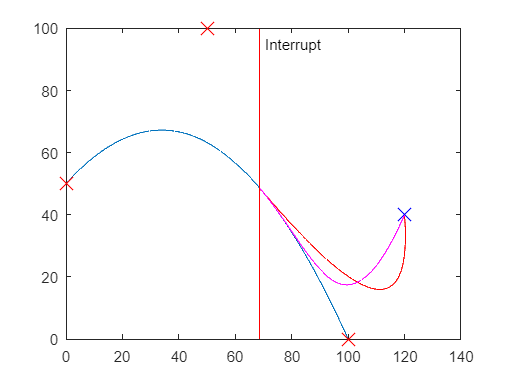


%RE-EVALUATE SPLINES
order = 3;
cSnapMAT = evaluate(reSCP, pmin, pstep, pmax, validpmin, validpmax, sknot, order);
order = 4;
cJerkMAT = evaluate(iJCP, pmin, pstep, pmax, validpmin, validpmax, ijknot, order);
order = 5;
cAccMAT = evaluate(iACP, pmin, pstep, pmax, validpmin, validpmax, iaknot, order);
order = 6;
cVelMAT = evaluate(iVCP, pmin, pstep, pmax, validpmin, validpmax, ivknot, order);
order = 7;
cPosMAT = evaluate(iCP, pmin, pstep, pmax, validpmin, validpmax, iknot, order);

%DISPLAY
%Replanner
plot(PosMAT(:,1), PosMAT(:,2))
hold on
scatter(CP(:,1), CP(:,2), 160, 'X', 'red')
scatter(NewTarg(1,1), NewTarg(1,2), 160, 'X', 'blue')
plot(RePlanMAT(:,1), RePlanMAT(:,2), 'red')
plot(cPosMAT(:,1), cPosMAT(:,2), 'magenta')
plot([PosMAT(Pauseloc,1), PosMAT(Pauseloc,1)], [0,100], 'red')
text(PosMAT(Pauseloc,1)+2, 95, 'Interrupt')
hold off

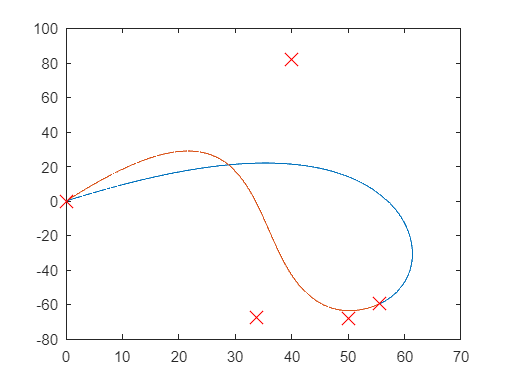


%Derivatives
plot(VelMAT(1:Pauseloc,1), VelMAT(1:Pauseloc,2))
hold on
plot(cVelMAT(:,1), cVelMAT(:,2))
scatter(iVCP(:,1), iVCP(:,2), 160, 'X', 'red')
hold off

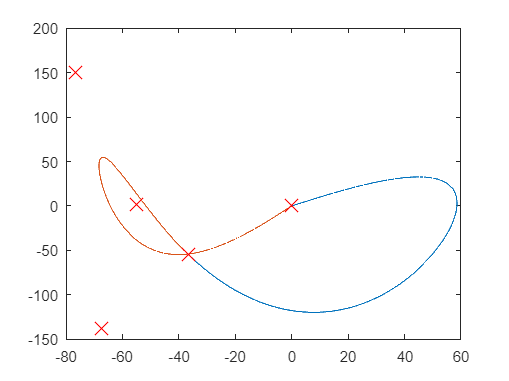

plot(AccMAT(1:Pauseloc,1), AccMAT(1:Pauseloc,2))
hold on
plot(cAccMAT(:,1), cAccMAT(:,2))
scatter(iACP(:,1), iACP(:,2), 160, 'X', 'red')
hold off

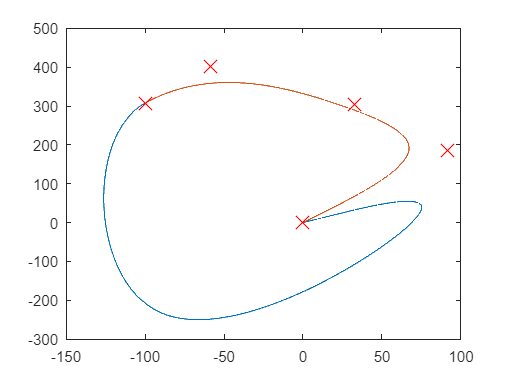

plot(JerkMAT(1:Pauseloc,1), JerkMAT(1:Pauseloc,2))
hold on
plot(cJerkMAT(:,1), cJerkMAT(:,2))
scatter(iJCP(:,1), iJCP(:,2), 160, 'X', 'red')
hold off

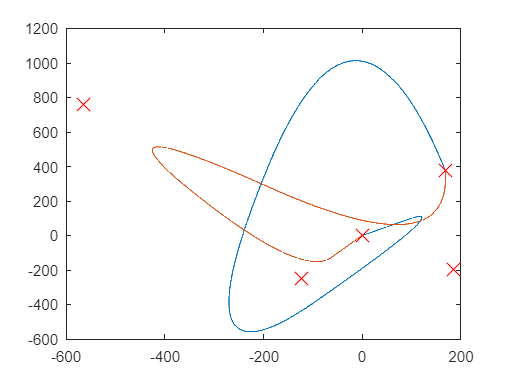

plot(SnapMAT(1:Pauseloc,1), SnapMAT(1:Pauseloc,2))
hold on
plot(cSnapMAT(:,1), cSnapMAT(:,2))
scatter(reSCP(:,1), reSCP(:,2), 160, 'X', 'red')
hold off

function [FullMAT, CPMAT, knotMAT] = PathPlanner(targets, pmin, pmax ,pstep)
    order = 7;
    CP = points(targets, order);
    CPx = CP(:,1);
    CPy = CP(:,2);
    %Knot Vector
    knot = knotvect(CP, order, pmin, pmax, pstep);
    ksz = size(knot);
    validpmin = knot(1, order);
    validpmax = knot(1, (ksz(1,2)-order+1));
    NK2MAT = [];
    NK3MAT = [];
    NK4MAT = [];
    NK5MAT = [];
    NK6MAT = [];
    NK7MAT = [];
    pM1 = [];
    pM2 = [];
    pM3 = [];
    pM4 = [];
    pM5 = [];
    pM6 = [];
    %Initial Path Plan
    PosMAT = evaluate(CP, pmin, pstep, pmax, validpmin, validpmax, knot, order);
    order = 6;
    VCP = DCP(CP, knot, order);
    vknot = Dkn(knot);
    VelMAT = evaluate(VCP, pmin, pstep, pmax, validpmin, validpmax, vknot, order);
    order = 5;
    ACP = DCP(VCP, vknot, order);
    aknot = Dkn(vknot);
    AccMAT = evaluate(ACP, pmin, pstep, pmax, validpmin, validpmax, aknot, order);
    order = 4;
    JCP = DCP(ACP, aknot, order);
    jknot = Dkn(aknot);
    JerkMAT = evaluate(JCP, pmin, pstep, pmax, validpmin, validpmax, jknot, order);
    order = 3;
    SCP = DCP(JCP, jknot, order);
    sknot = Dkn(jknot);
    SnapMAT = evaluate(SCP, pmin, pstep, pmax, validpmin, validpmax, sknot, order);
    BearingMAT = direc(VelMAT);

    %Load all data into matrix for function return
    FullMAT = [PosMAT, VelMAT, AccMAT, JerkMAT, SnapMAT, BearingMAT];
    CPMAT = [CP, [VCP; 0,0], [ACP;0,0;0,0], [JCP;0,0;0,0;0,0], [SCP;0,0;0,0;0,0;0,0]];
    knotMAT = [knot; [vknot, 0, 0]; [aknot,0,0,0,0]; [jknot,0,0,0,0,0,0]; [sknot,0,0,0,0,0,0,0,0]];
end  
function pMAT = pMAT(p,knot,k)
        N = length(knot);
        pMAT = [];
        for i = 1:1:N-k
            pconst1 = (p-knot(1,i))/(knot(1,i+k-1)-knot(1, i));
            pconst2 = (knot(1,i+k)-p)/(knot(1,i+k)-knot(1,i+1));
            Head = zeros(i-1,1);
            Foot = zeros(N-k-i,1);
            pvect = [Head; pconst1; pconst2; Foot];
            pMAT = [pMAT, pvect];
        end
end
function CP = points(targets, order)
        P = height(targets);
        rep = order - 1;
        CP = [];
        hold = [targets(1,1), targets(1,2)];
        for n = 1:1:rep
            CP = [CP; hold];
        end
        for i = 2:1:P-1
            hold = [targets(i,1), targets(i,2)];
            CP = [CP; hold];
        end
        hold = [targets(P,1), targets(P,2)];
        for k = 1:1:rep
            CP = [CP; hold];
        end
end
function Knot = knotvect(CP, order, pmin, pmax, pstep)
        %ALTERED FUNCTION WITH P RANGE TO CONSIDER INITIAL TIME AFTER
        %INTERRUPT AND NOT REVERT TO ZERO
        sz = size(CP);
        P = sz(1,1);
        K = P + order;
        prange = pmax-pmin;
        Knot = pmin;
        for i = 1:1:order-1
            Knot = [Knot, pmin+i*pstep];
        end
        for i = 1:1:K-2*order
            Knot = [Knot, pmin+i*prange/(K-2*order+1)];
        end
        for i = 1:1:order
            Knot = [Knot, pmax-(order-i)*pstep];
        end
end
function NK1MAT = NK1MAT(p, knot)
        N = length(knot);
        NK1MAT = [];
        for i = 1:1:N-1
            lowkn = knot(i);
            highkn = knot(i+1);
            if lowkn<=p && p<highkn
                NK1MAT = [NK1MAT, 1];
            else
                NK1MAT = [NK1MAT, 0];
            end
        end
end
function BSplineMAT = evaluate(CP, pmin, pstep, pmax, validpmin, validpmax, knot, order)
        BSplineMAT = [];
        for p = pmin:pstep:pmax
            if p >= validpmin
                if p<=validpmax
                    k = 2;
                    NK2MAT = NK1MAT(p, knot)*pMAT(p, knot, k);
                    k = 3;
                    NK3MAT = NK2MAT*pMAT(p, knot, k);
                    k = 4;
                    if order < k
                        Pos = NK3MAT*CP;
                    else
                        NK4MAT = NK3MAT*pMAT(p, knot, k);
                        k = 5;
                        if order < k
                            Pos = NK4MAT*CP;
                        else
                            NK5MAT = NK4MAT*pMAT(p, knot, k);
                            k = 6;
                            if order < k
                                Pos = NK5MAT*CP;
                            else
                                NK6MAT = NK5MAT*pMAT(p, knot, k);
                                k = 7;
                                if order < k
                                    Pos = NK6MAT*CP;
                                else
                                    NK7MAT = NK6MAT*pMAT(p, knot, k);
                                    Pos = NK7MAT*CP;
                                end
                            end
                        end
                    end
                    BSplineMAT = [BSplineMAT; Pos];
                end
            end
        end
end
function DP = DCP(CP, knot, k)
        n = length(CP);
        DP = [];
        for i = 1:1:n-1
            I = i+1;
            P1 = [CP(i,1),CP(i,2)];
            P2 = [CP(i+1,1),CP(i+1,2)];
            DPnew = (P2-P1)*k/(knot(I+k)-knot(I));
            DP = [DP; DPnew];
        end
end
function DKnot = Dkn(knot)
        N = length(knot);
        DKnot = [];
        for i = 1:1:N-2
            DKnew = knot(i+1);
            DKnot = [DKnot, DKnew];
        end
end
function MagMAT = absBS(Pos)
        N = length(Pos.');
        MagMAT = [];
        for i = 1:1:N
            X = Pos(i,1);
            Y = Pos(i,2);
            abs = sqrt(X^2+Y^2);
            MagMAT = [MagMAT; i, abs];
        end
end
function bearingMAT = direc(Vel)
        N = length(Vel.');
        bearingMAT = [];
        for i = 1:1:N
            X = Vel(i,1);
            Y = Vel(i,2);
            vtan = (360*atan(X/Y))/(2*pi);
            if X >= 0 && Y >= 0
                dir = vtan;
                sect = 1;
            end
            if X >= 0 && Y < 0
                dir = 180 + vtan;
                sect = 2;
            end
            if X < 0 && Y >= 0
                dir = 360 + vtan;
                sect = 3;
            end
            if X < 0 && Y < 0
                dir = 180 + vtan;
                sect = 4;
            end
            bearingMAT = [bearingMAT; i, dir, sect];
        end
end
function IP = ICP(CP, knot, k, c)
    CPx = CP(:,1);
    CPy = CP(:,2);
    n = length(CP);
    IP1 = c;
    IP = IP1;
    for i = 1:1:n
        xhold = CPx(i);
        yhold = CPy(i);
        IP2x = xhold*(knot(i+1+k)-knot(i+1))/k + IP1(1,1);
        IP2y = yhold*(knot(i+1+k)-knot(i+1))/k + IP1(1,2);
        IP = [IP; IP2x, IP2y];
        IP1 = [IP2x, IP2y];
    end
end
function Iknot = Ikn(knot, pstep)
    n = length(knot);
    Iknot = knot(1)-pstep;
    for i = 1:1:n
        Iknot = [Iknot, knot(i)];
    end
    Iknot = [Iknot, knot(n)+pstep];
end
function iP = corrector(CP, iP, iknot, M, k)
    CPx = CP(:,1);
    CPy = CP(:,2);
    n = length(CP);
    IP1 = iP(M, :);
    for i = M:1:n
        xhold = CPx(i);
        yhold = CPy(i);
        IP2x = xhold*(iknot(i+1+k)-iknot(i+1))/k + IP1(1,1);
        IP2y = yhold*(iknot(i+1+k)-iknot(i+1))/k + IP1(1,2);
        IP2x = round(IP2x,4);
        IP2y = round(IP2y,4);
        iP(i+1, 1) = IP2x;
        iP(i+1, 2) = IP2y;
        IP1 = [IP2x, IP2y];
    end
end